clc; close all; clearvars; close all;
colormap jet
VoronoiData = load("VoronoiData.mat").VelocityData;
[rows, columns] = size(VoronoiData);
Noise_Scaling_Factor = 30 %scaling factor

Noise_Scaling_Factor = 30

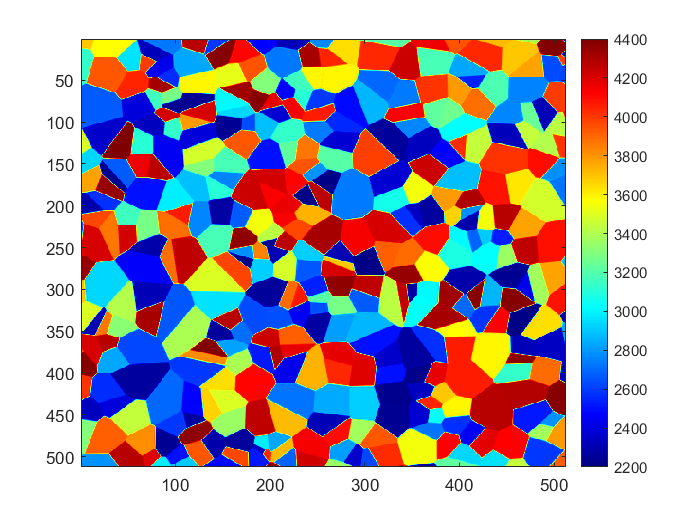

Noise_Addon = randn([rows, columns])  * Noise_Scaling_Factor;
imagesc(VoronoiData);

colorbar

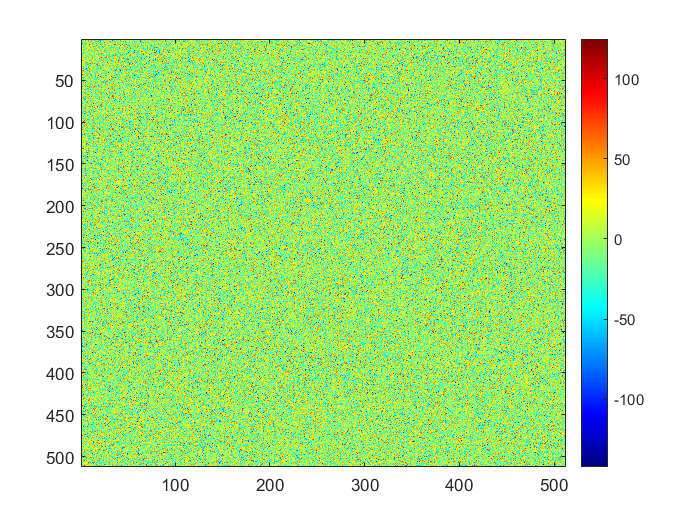

imagesc(Noise_Addon);
%colormap jet
colorbar

noisy_voronoi= VoronoiData+Noise_Addon;
save("NoisyVoronoiData.mat", 'noisy_voronoi')
NoisyMapSimulation = imagesc(noisy_voronoi);
%colormap jet
axis off
saveas(NoisyMapSimulation,'noisy_voronoi.png');
axis on
colorbar
rgbImage = imread('Noisy_Voronoi.png');
rgbImage = CropFrame(rgbImage);
rgbImage = imresize(rgbImage, [512, 512]);
[rows, columns, numberOfChannel] = size(rgbImage);
fprintf("[Info] Image resolution - row: %d column: %d ", rows, columns);

[Info] Image resolution - row: 512 column: 512 

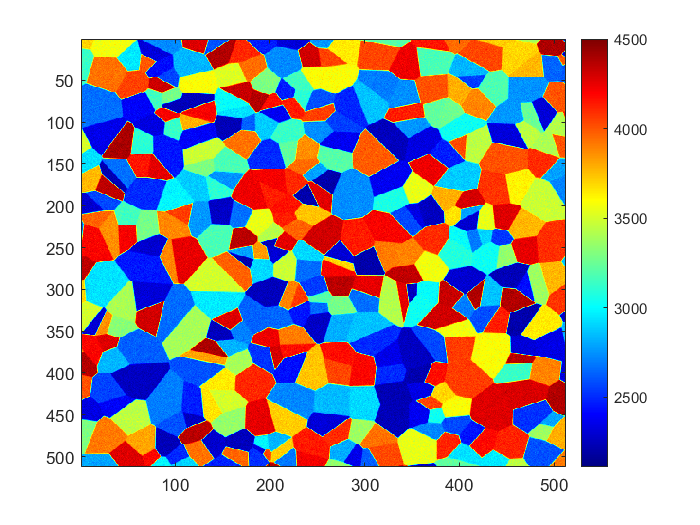

imwrite(rgbImage, "noisy_voronoi.png");
hold off